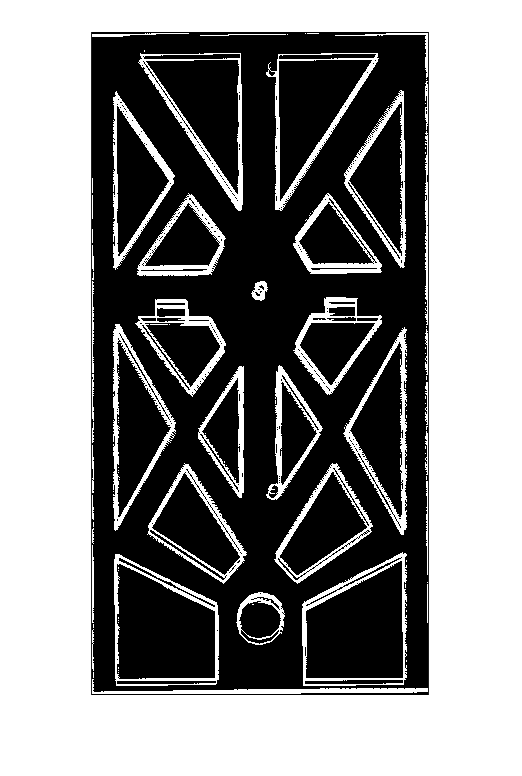

clearvars

mapSize.scale = 50;
mapSize.placingResolution = 100;
mapSize.x = round(26.5*mapSize.scale);
mapSize.y = round(13.5*mapSize.scale);

BW = zeros(mapSize.x,mapSize.y);
robotName = 'Marvin';
laserName = 'LMS100';

for x = 1:mapSize.x
    for y = 1:mapSize.y
        if 0 == mod(x,mapSize.placingResolution)
            % Front
            apoloPlaceMRobot(robotName, [x/mapSize.scale,y/mapSize.scale,0], 0);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            for i = 1:length(ld)
                angl = (i/length(ld))*3*pi/2 - 3*pi/4;
                dist = ld(i);
                if dist < 10
                    % Rellenamos un pixel encontrado
                    indx = min([mapSize.x-1,max([2,     round(x+cos(angl)*dist*mapSize.scale)])]);
                    indy = min([mapSize.y-1,max([2,     round(y+sin(angl)*dist*mapSize.scale)])]);
                    BW(indx,indy) = 255;
                end
            end
            pause(0.001)
            % Back
            apoloPlaceMRobot(robotName, [x/mapSize.scale,y/mapSize.scale,0], pi);
            ld = apoloGetLaserData(laserName);
            apoloUpdate();
            for i = 1:length(ld)
                angl = (i/length(ld))*3*pi/2 - 3*pi/4 -pi;
                dist = ld(i);
                if dist < 10
                    % Rellenamos un pixel encontrado
                    indx = min([mapSize.x-1,max([2,     round(x+cos(angl)*dist*mapSize.scale)])]);
                    indy = min([mapSize.y-1,max([2,     round(y+sin(angl)*dist*mapSize.scale)])]);
                    BW(indx,indy) = 255;
                end
            end
            pause(0.001)
        end
    end
end

imshow(BW)

mapRaw = BW;
save('jardinBinMapParsed.mat',"BW");

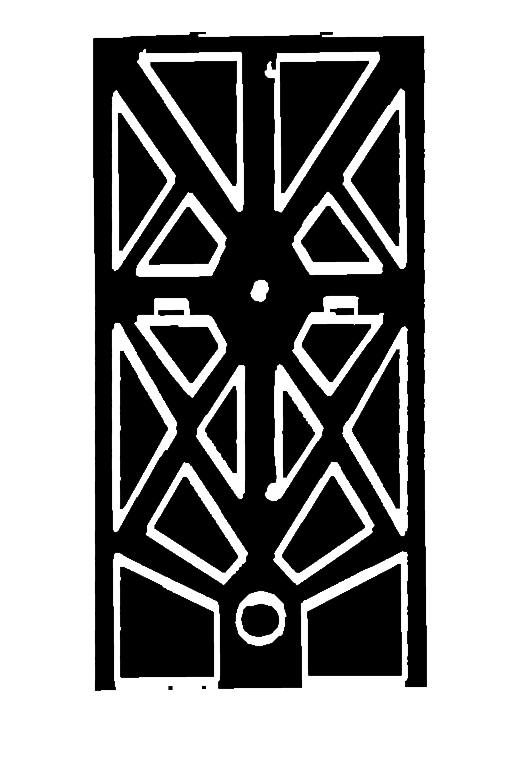

se = offsetstrel('ball',5,5);
BW = imdilate(mapRaw,se);
se = offsetstrel('ball',7,7);
BW = imerode(BW,se);

imshow(BW)

save('jardinBinMapCorrectAndDilated.mat',"BW");